Ejercicio 2

% Parámetros del sistema
Kp = 20;      % Ganancia del controlador proporcional
Q = 0.5;      % Coeficiente de la electroválvula
C = 0.6;      % Coeficiente de salida proporcional a la altura
B = 2;        % Parámetro del sensor
D = 2;        % Parámetro del sensor
A = 10;       % Área del depósito

a)Realizar un modelo en Simulink donde se simule el funcionamiento de la planta en lazo abierto por un lado y el del sistema realimentado con controlador por otro. Determinar en base a la respuesta de la planta el orden y tipo del sistema. Comentar la respuesta con el controlador proporcional en terminos de precisión, sobreoscilación y tiempo de asentamiento.

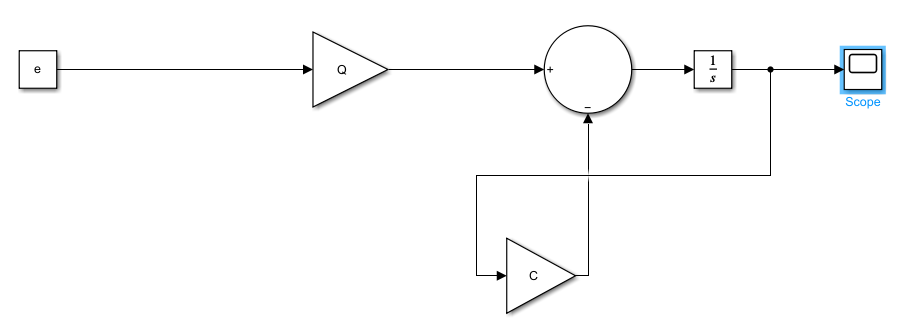

Este es un sistema dinámico de primer orden en el cual la variable de salida depende de su propia derivada y de la entrada (voltaje de la electroválvula). Como tiene una derivada de primer orden y una sola constante de tiempo involucrada en la dinámica, podemos decir que es un sistema de primer orden.

El tipo del sistema depende de la cantidad de integradores presentes en la función de transferencia de la planta. En este caso, hay un integrador en la planta, esto hace que sea de tipo 1.

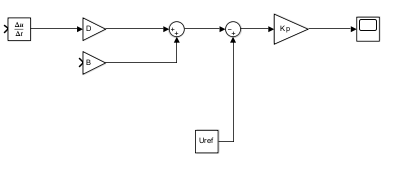

El error en régimen permanente no se eliminará completamente porque el sistema es de tipo 0. Habrá un error constante en estado estacionario.

Dependiendo de Uref�, la respuesta podría mostrar sobreoscilación si Uref� es muy alto. Si Uref es bajo, la respuesta será más lenta y menos propensa a sobreoscilación.

El tiempo de asentamiento dependerá de la constante de tiempo del sistema. A mayor Uref�, el tiempo de asentamiento puede reducirse, pero se corre el riesgo de generar oscilaciones.

b)Mostrar la respuesta del sistema controlado en caso de que el caudal de entrada se vea afectado por un fallo de la válvula que le sume 2 m3/𝑠𝑠 una vez estabilizada la altura del depósito. Mostrar también la velocidad de variación de la altura así como la respuesta de los caudales de salida y entrada. Describir la evolución de dichas variables respecto a la salida y como se relacionan con la salida una vez alcanzado el régimen permanente.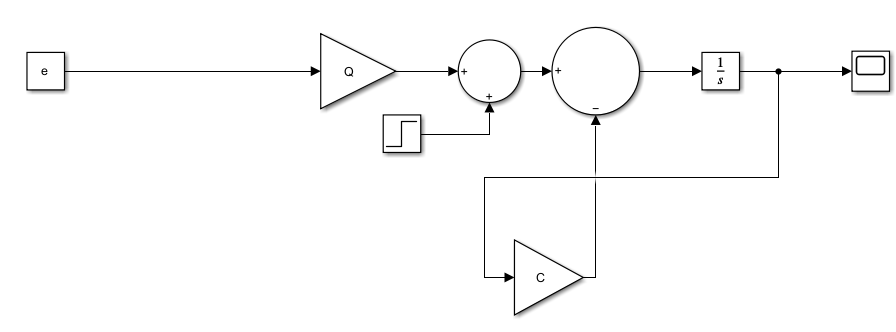

En la fase previa a la perturbación, el sistema está en régimen permanente con una altura constante h(t), y los caudales de entrada y salida están equilibrados.

La perturbación en el caudal de entrada genera un desequilibrio, lo que provoca un aumento en la altura h(t), una mayor velocidad de variación de la altura y un incremento temporal en el caudal de salida qs(t).

Finalmente, el sistema alcanza un nuevo régimen permanente con un valor mayor de la altura h(t) y un caudal de salida qs(t) ajustado a la nueva altura.

c) Se pretende sustituir el amplificador por el controlador PID más sencillo para eliminar el error en regimen permanente, trabajar de forma críticamente amoriguada y con tiempo de establecimiento de 2.75 segundos. Mostrar la gráfica de respuesta obtenida, junto con el diseño del controlador y la FT de este. ¿Cuánto tarda en estabilizarse realmente la altura del depósito?¿ Cómo afecta ahora la perturbación de caudal del apartado anterior?.

s = tf('s');
G = Q / (A * s + C); % Función de transferencia de la planta
H = 1; % Sensor con ganancia unitaria

% Diseñar un PID para eliminar el error en régimen permanente
sisotool(G, H);

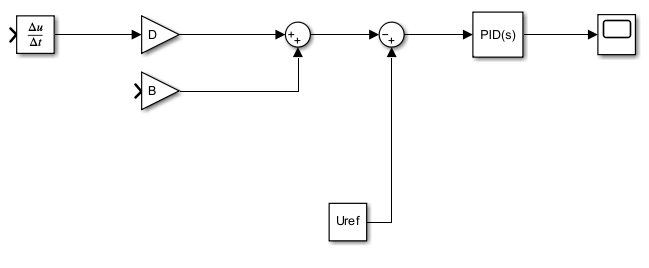

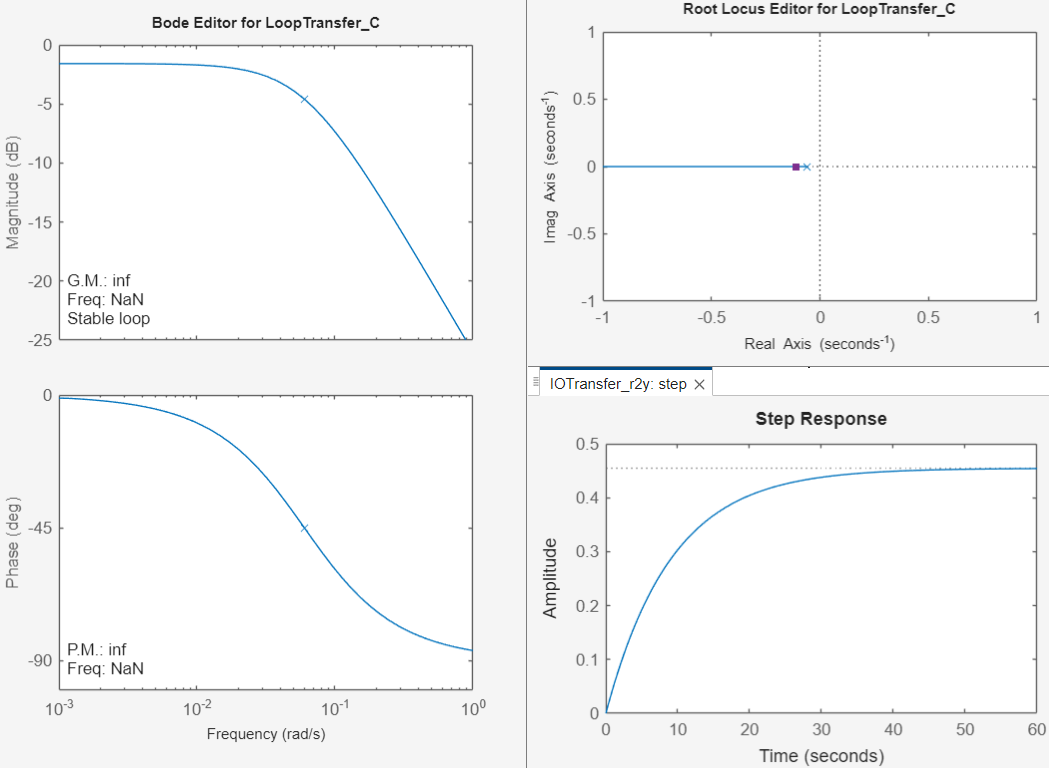

d) ¿Qué ocurre con la precisión en regimen permanente si la ganancia estática de la función de transferencia del sensor no fuese unitaria? Mostrar el efecto sobre la respuesta del apartado anterior (sin perturbación) con una ganancia estática de 0.5 y comentar el por qué de la diferencia.

Con Gs=0.5 el sistema presenta un error en régimen permanente mayor porque la retroalimentación no refleja correctamente la altura real.

La altura real h(t) será mayor que la referencia Uref�.

La retroalimentación y(t) coincidirá con Uref�, pero esto no implica que la altura real sea igual a la referencia.